# USA'S STORM EVENTS 2017

## Background and Scope

### Import the Data

events = importStormEvents2017("StormEvents_2017_finalProject.csv");
events = removevars(events, {'EpisodeID','Event_ID','Timezone','Episode_Narrative','Event_Narrative'})

events = 57005×19 table
        State         Year     Month            Event_Type                               CZ_Name                           Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ______________    ____    _______    ________________________    ________________________________________________    ___________________    ___________________    ______

%States impacted by Harvey
events = events(ismember(events.State,{'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);

%Harvey related events occured from 17th Aug. to 3rd Sept.
events = events(events.Begin_Date_Time >= '2017-08-17 00:00:00' & events.Begin_Date_Time < '2017-09-03 23:23:01' | ismissing(events.Begin_Date_Time),:)

events = 579×19 table
        State         Year      Month         Event_Type          CZ_Name        Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ______________    ____    _________    _________________    ___________    ___________________    ___________________    _______________    _________________    _____________

#### Two States Most impacted by Harvey

events.Total_Cost = events.Property_Cost + events.Crop_Cost;
events = movevars(events, 'Total_Cost', 'Before', 'Begin_Lat')

events = 579×20 table
        State         Year      Month         Event_Type          CZ_Name        Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Total_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ______________    ____    _________    _________________    ___________    ___________________    ___________________    _______________    _________________

events = events(~ismissing(events.Property_Cost),:);
events = events(~ismissing(events.Crop_Cost),:);
most_ImpactedState_Harvey = groupsummary(events, "State", "max", "Total_Cost");
most_ImpactedState_Harvey = sortrows(most_ImpactedState_Harvey,'max_Total_Cost','descend')

most_ImpactedState_Harvey = 7×3 table
        State         GroupCount    max_Total_Cost
    ______________    __________    ______________

    TEXAS                243             1e+10    
    LOUISIANA             86             6e+07    
    NORTH CAROLINA        48             1e+07    
    KENTUCKY              17           3.5e+05    
    MISSISSIPPI           39             2e+05    
    TENNESSEE             46             2e+05    
    ARKANSAS              53             20000    


*The two states most impacted by Harvey are**** "TEXAS" ****and ****"LOUISIANA".***

#### Table of Events for Two Most Impacted States

events_TEXAS_LOUISIANA = events(ismember(events.State,{'LOUISIANA','TEXAS'}),:)

events_TEXAS_LOUISIANA = 329×20 table
      State      Year    Month        Event_Type         CZ_Name        Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Total_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    _________    ____    ______    _________________    __________    ___________________    ___________________    _______________    _________________ 

events_TEXAS_LOUISIANA = events_TEXAS_LOUISIANA(~ismissing(events_TEXAS_LOUISIANA.Event_Type),:)

events_TEXAS_LOUISIANA = 329×20 table
      State      Year    Month        Event_Type         CZ_Name        Begin_Date_Time         End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Total_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    _________    ____    ______    _________________    __________    ___________________    ___________________    _______________    _________________ 

### Visualizations

#### Figure of Event Types

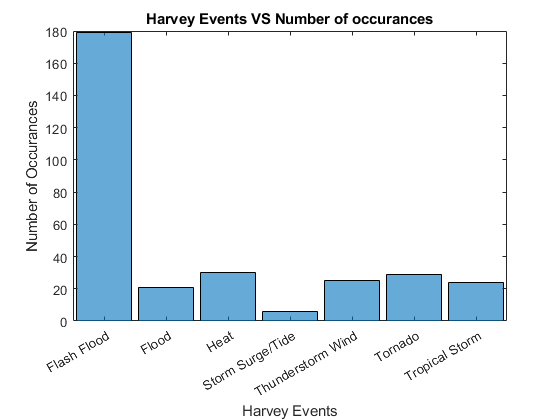

histogram(events_TEXAS_LOUISIANA.Event_Type, ["Flash Flood", "Flood", "Heat", "Storm Surge/Tide", "Thunderstorm Wind", "Tornado", "Tropical Storm"])

title('Harvey Events VS Number of occurances')
xlabel('Harvey Events')
ylabel('Number of Occurances')

### Figure of Event Locations

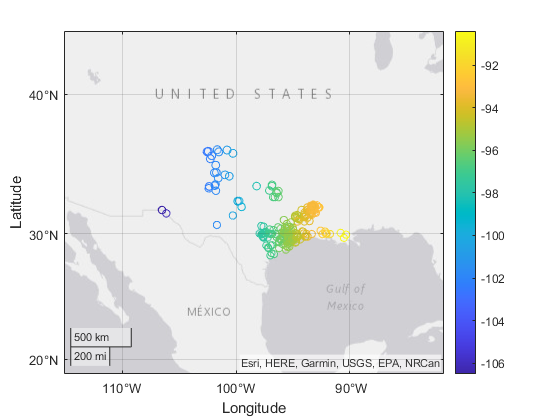

geoscatter(events_TEXAS_LOUISIANA.Begin_Lat,events_TEXAS_LOUISIANA.Begin_Lon,events_TEXAS_LOUISIANA.End_Lat,events_TEXAS_LOUISIANA.End_Lon);
colorbar

## Analysis

### Three Counties with Most Events in State 1 (TEXAS)

events_TEXAS = events_TEXAS_LOUISIANA(events_TEXAS_LOUISIANA.State == 'TEXAS',:);
events_LOUISIANA = events_TEXAS_LOUISIANA(events_TEXAS_LOUISIANA.State == 'LOUISIANA',:);

texas_Most_Counties = groupsummary(events_TEXAS, "CZ_Name");
texas_Most_Counties = sortrows(texas_Most_Counties,'GroupCount','descend')

texas_Most_Counties = 90×2 table
     CZ_Name      GroupCount
    __________    __________

    HARRIS            20    
    GALVESTON         15    
    ANGELINA          12    
    SABINE            12    
    FORT BEND         11    
    BASTROP            9    
    BRAZORIA           9    
    CALDWELL           7    
    CHAMBERS           7    
    JEFFERSON          5    
    MONTGOMERY         5    
    CALHOUN            4    
    FAYETTE            4    
    MATAGORDA          4    
    WHARTON            4    
    EL PASO            3    


***Harris, Galveston, Angelina ****are the three counties with the most events in TEXAS.*

### Three Counties with Most Events in State 2 (LOUISIANA)

louisiana_Most_Counties = groupsummary(events_LOUISIANA, "CZ_Name");
louisiana_Most_Counties = sortrows(louisiana_Most_Counties,'GroupCount','descend')

louisiana_Most_Counties = 30×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    
    WINN                 6    
    CAMERON              4    
    VERMILION            4    
    DE SOTO              3    
    UNION                2    
    ACADIA               1    
    BEAUREGARD           1    
    BIENVILLE            1    
    BOSSIER              1    
    CADDO                1    
    CALCASIEU            1    
    CALDWELL             1    
    CLAIBORNE            1    


***Natchitoches, Sabine, and Red River ****are the three counties with the most events in LOUISIANA.*

### Three Counties with Highest Property Cost in State 1 (TEXAS)

texas_Highest_Prop_Cost = groupsummary(events_TEXAS, "CZ_Name", "max", "Property_Cost");
texas_Highest_Prop_Cost = sortrows(texas_Highest_Prop_Cost,'max_Property_Cost','descend')

texas_Highest_Prop_Cost = 90×3 table
      CZ_Name       GroupCount    max_Property_Cost
    ____________    __________    _________________

    GALVESTON           15               1e+10     
    HARRIS              20               1e+10     
    FORT BEND           11               8e+09     
    MONTGOMERY           5               7e+09     
    JEFFERSON            5               3e+09     
    BRAZORIA             9               2e+09     
    ORANGE               3             1.5e+09     
    NUECES               1               1e+09     
    HARDIN               1               6e+08     
    WALKER               3               6e+08     
    REFUGIO              3               5e+08     
    SAN PATRICIO         1               5e+08     
    SAN JACINTO          2             3.5e+08     
    POLK                 1               3e+08     
    CALHOUN              4  

***Galveston, Harris, and Fort Bend ****are the three counties with highest property cost in TEXAS.*

### Three Counties with Highest Property Cost in State 2 (LOUISIANA)

louisiana_Highest_Prop_Cost = groupsummary(events_LOUISIANA, "CZ_Name", "max", "Property_Cost");
louisiana_Highest_Prop_Cost = sortrows(louisiana_Highest_Prop_Cost,'max_Property_Cost','descend')

louisiana_Highest_Prop_Cost = 30×3 table
      CZ_Name       GroupCount    max_Property_Cost
    ____________    __________    _________________

    CALCASIEU           1                6e+07     
    BEAUREGARD          1              1.5e+07     
    ACADIA              1                2e+05     
    CAMERON             4                50000     
    VERMILION           4                 5000     
    BIENVILLE           1                    0     
    BOSSIER             1                    0     
    CADDO               1                    0     
    CALDWELL            1                    0     
    CLAIBORNE           1                    0     
    DE SOTO             3                    0     
    EAST CAMERON        1                    0     
    GRANT               1                    0     
    IBERIA              1                    0     
    JACKSON             

***Calcasieu, Beauregard, and Acadia ****are the three counties with highest property cost in LOUISIANA.*

### Conclusions and Recommendation

According to the exploratory data analysis on the dataset STORMEVENTS_2017_FINALPROJECT, we can say that: -

- Two states most impacted by Harvey Events were **TEXAS** and **LOUISIANA**.

- According to the visualisation, **FLASH FLOODS** contributed the most to Harvey Events and **TEXAS** and **LOUISIANA** have seen a lot more events.

- Three counties with the most events in Texas were **HARRIS, GALVESTON, **and** ANGELINA**.

- Three counties with the most events in Louisiana were **NATCHITOCHES, SABINE, **and** RED RIVER**.

- Three counties with the highest property cost in Texas were **GALVESTON, HARRIS, **and** FORT BEND**.

- Three counties with the highest property cost in Louisiana were **CALCASIEU, BEAUREGARD, **and** ACADIA**.

I would like to *recommend* the management to send the contractors to **HARRIS, GALVESTON, FORT BEND** in a chronological order (top most priority to least most) to adjust the claims.